# Otimização do atributo funcional via árvores morfológicas e algoritmos genéticos

Este código apresenta alguns exemplos de uso da função AGMS para otimização do atributo funcional via árvores morfológicas e algoritmos genéticos .

## Definição do atributo funcional

Seja $$\mathcal{T}$$ uma árvore morfológica e $P_{\mathcal{T}}$ sua partição associada. Então o atributo funcional para um dada região $\tau' \in P_\mathcal{T}$ é definido como:


$$\kappa_{ms}(\tau')=\frac{[vol(\tau')]^2}{|\tau'|} + \frac{[vol(\tau'')]^2}{|\tau''|} -  \frac{[vol(\tau''')]^2}{|\tau'''|} \times \frac{1}{|\partial \tau'|+|\partial \tau''|-|\partial \tau'''|}$$


onde $$ \tau'' = Pai(\tau') $$ e $$ \tau''' = \tau'' \cup \tau' $$. Quanto maior o valor de $\kappa_{ms}(\tau')$ maior a significância do nó, portanto deve-se remover nós com o menor valor de $\kappa_{ms}$.

## Função AGMS

Resumo das opções da função AMGS.

**Entrada**

*imgFile*       =   (String)     Endereço da imagem.

*typeOfTree* =   (String)     Tipo da árvore: *MaxTree* ou *MinTree*.

*debug*         =   (boolean)  Debug da classe mmlib4j.

**Saída**

*solution = Solução com os métodos ****remove****, ****fitness, numnode**** e ****result.***

- ***método fitness     = ***recebe um id de um dado nó $\tau' \in P_{\mathcal{T}}$ e computa o atributo funcional de $\tau'$. Retorna $\infty$ se o nó já foi removido. 

- ***método remove    = ***recebe um id de um dado nó $\tau' \in P_{\mathcal{T}}$  e remove o nó da árvore $\mathcal{T}$. A remoção faz um *merge* entre o nó $\tau'$ e seu pai $\tau''$.

- ***método numnode = ***retorna o número de nós da árvore após sua construção. 

- ***método result ***   ***   =*** imagem simplificada após as remoções.

Dois exemplos são dados abaixo, um para *MaxTree* e outro para *MinTree*.

# Exemplos

Seguem dois exemplos de utilização da solução retornada por AGMS.

## Maxtree

% Limpando as variáveis
clear; clc;

% Construindo a solução
solution = AGMS('../images/mumford-image-test.png',...
                'MaxTree',... 
                false);

% Valor do atributo para um dado nó            
disp("(MaxTree) Energia do nó 10 = "+ solution.fitness(10));            

Energia do nó 10 = 355.5433


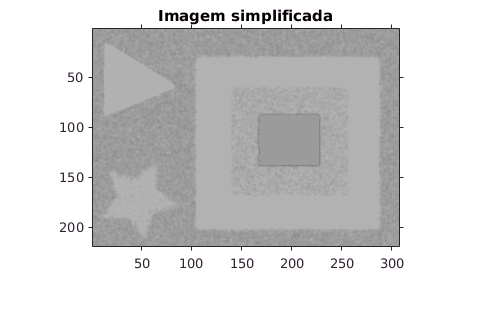


% Removendo os nós entre o intervalo 6000 e numnode()-1          
for i=6000:solution.numnode()-1
    solution.remove(i);
end

% Mostrando o resultado
imshow(solution.result()); 
h = gca;
h.Visible = 'On';
title('Imagem simplificada');
truesize;

## MinTree

% Limpando as variáveis
clear; clc;

% Construindo a solução
solution = AGMS('../images/mumford-image-test.png',...
                'MinTree',... 
                false);

% Valor do atributo para um dado nó            
disp("(MinTree) Energia do nó 10 = "+ solution.fitness(10));


Energia do nó 10 = 323.5053


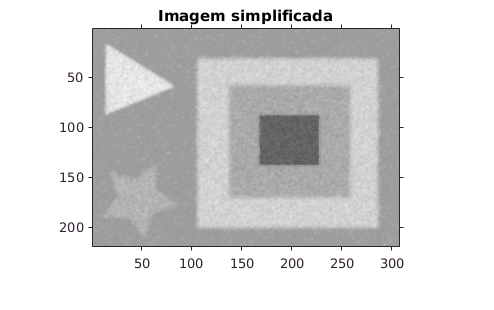

% Removendo os nós entre o intervalo 5000 e numnode()-1          
for i=5000:solution.numnode()-1
    solution.remove(i);
end

% Mostrando o resultado
imshow(solution.result());
h = gca;
h.Visible = 'On';
title('Imagem simplificada');
truesize;